1. Загрузите данные **ex4data1.mat **из файла.

load('ex4data1.mat');

2. Загрузите веса нейронной сети из файла **ex4weights.mat**, который содержит две матрицы Θ(1) (25, 401) и Θ(2) (10, 26). Какова структура полученной нейронной сети?

load('ex4weights.mat');

3. Реализуйте функцию прямого распространения с сигмоидом в качестве функции активации. 

4. Вычислите процент правильных классификаций на обучающей выборке. Сравните полученный результат с логистической регрессией.

pred = predict(Theta1, Theta2, X);
fprintf('\nTraining Set Accuracy: %f\n', mean(double(pred == y)) * 100);


Training Set Accuracy: 97.520000


difference = mean(double(pred == y)) * 100 - 94.78

difference = 2.7400

Результат лучше на 2.74%

6. Реализуйте функцию стоимости для данной нейронной сети.

7. Добавьте L2-регуляризацию в функцию стоимости.

8. Реализуйте функцию вычисления производной для функции активации.

9. Инициализируйте веса небольшими случайными числами.

initial_Theta1 = randInitializeWeights(input_layer_size, hidden_layer_size);
initial_Theta2 = randInitializeWeights(hidden_layer_size, num_labels);

initial_Theta2 =    -0.0648    0.0942    0.0642   -0.0031   -0.0347    0.1164    0.0471    0.0826   -0.0287    0.0393   -0.0505    0.0352   -0.0177   -0.0092   -0.0743    0.1053   -0.0013    0.0593    0.0458   -0.0807   -0.0978    0.0818    0.0376   -0.0658   -0.0595   -0.0872
    0.1190   -0.0022    0.0795    0.0875   -0.1112   -0.0429    0.0051    0.0871   -0.0319    0.0173    0.0684   -0.1052   -0.0203    0.0261   -0.0517   -0.0827   -0.0090   -0.0425    0.1180    0.0096    0.0998   -0.0538    0.0016    0.0181    0.0403    0.0707
   -0.1054    0.1127    0.0766   -0.0693    0.0856    0.1166   -0.0595    0.1093   -0.0177   -0.0857   -0.0621   -0.0966    0.0099    0.0991    0.0349   -0.0821   -0.0103   -0.0027   -0.0945    0.0616   -0.0936   -0.1102    0.1091   -0.0869   -0.0710   -0.0813
   -0.0351    0.0509   -0.0543    0.0510   -0.0384   -0.0752   -0.0356    0.0902   -0.0635   -0.1010    0.0114    0.0448    0.0753    0.0366    0.0274   -0.0624    0.1162   -0.1000   -0.0030   -0.0531

initial_nn_params = [initial_Theta1(:) ; initial_Theta2(:)];

10. Реализуйте алгоритм обратного распространения ошибки для данной конфигурации сети.

11. Для того, чтобы удостоверится в правильности вычисленных значений градиентов используйте метод проверки градиента с параметром ε = 10-4.

12. Добавьте L2-регуляризацию в процесс вычисления градиентов.

13. Проверьте полученные значения градиента.

lambda = 3;
checkNNGradients(lambda);

   -0.0093   -0.0093
    0.0089    0.0089
   -0.0084   -0.0084
    0.0076    0.0076
   -0.0067   -0.0067
   -0.0168   -0.0168
    0.0394    0.0394
    0.0593    0.0593
    0.0248    0.0248
   -0.0327   -0.0327
   -0.0602   -0.0602
   -0.0320   -0.0320
    0.0249    0.0249
    0.0598    0.0598
    0.0386    0.0386
   -0.0174   -0.0174
   -0.0576   -0.0576
   -0.0452   -0.0452
    0.0091    0.0091
    0.0546    0.0546
    0.3145    0.3145
    0.1111    0.1111
    0.0974    0.0974
    0.1187    0.1187
    0.0000    0.0000
    0.0337    0.0337
    0.2040    0.2040
    0.1171    0.1171
    0.0755    0.0755
    0.1257    0.1257
   -0.0041   -0.0041
    0.0170    0.0170
    0.1763    0.1763
    0.1131    0.1131
    0.0862    0.0862
    0.1323    0.1323
   -0.0045   -0.0045
    0.0015    0.0015

The above two columns you get should be very similar.
(Left-Your Numerical Gradient, Right-Analytical Gradient)

If your backpropagation implementation is correct, then 
the relative difference will be

debug_J  = nnCostFunction(nn_params, input_layer_size, hidden_layer_size, num_labels, X, y, lambda);
fprintf('Cost at (fixed) debugging parameters (w/ lambda = 3): %f', debug_J);

Cost at (fixed) debugging parameters (w/ lambda = 3): 0.576051

14. Обучите нейронную сеть с использованием градиентного спуска или других более эффективных методов оптимизации.

15. Вычислите процент правильных классификаций на обучающей выборке.

options = optimset('MaxIter', 50);
lambda = 1;
costFunction = @(p) nnCostFunction(p, input_layer_size, hidden_layer_size, num_labels, X, y, lambda);
[nn_params, ~] = fmincg(costFunction, initial_nn_params, options);

Iteration     1 | Cost: 3.309932e+00
Iteration     2 | Cost: 3.242441e+00
Iteration     3 | Cost: 3.192405e+00
Iteration     4 | Cost: 2.798920e+00
Iteration     5 | Cost: 2.487892e+00
Iteration     6 | Cost: 2.399977e+00
Iteration     7 | Cost: 2.198364e+00
Iteration     8 | Cost: 1.839534e+00
Iteration     9 | Cost: 1.703839e+00
Iteration    10 | Cost: 1.645288e+00
Iteration    11 | Cost: 1.458893e+00
Iteration    12 | Cost: 1.390983e+00
Iteration    13 | Cost: 1.206240e+00
Iteration    14 | Cost: 1.097810e+00
Iteration    15 | Cost: 1.064724e+00
Iteration    16 | Cost: 9.644210e-01
Iteration    17 | Cost: 9.224633e-01
Iteration    18 | Cost: 8.689206e-01
Iteration    19 | Cost: 8.369293e-01
Iteration    20 | Cost: 8.131476e-01
Iteration    21 | Cost: 7.794444e-01
Iteration    22 | Cost: 7.654357e-01
Iteration    23 | Cost: 7.576890e-01
Iteration    24 | Cost: 7.486774e-01
Iteration    25 | Cost: 7.286269e-01
Iteration    26 | Cost: 7.187079e-01
Iteration    27 | Cost: 7.110450e-01
I

Theta1 = reshape(nn_params(1:hidden_layer_size * (input_layer_size + 1)), hidden_layer_size, (input_layer_size + 1));
Theta2 = reshape(nn_params((1 + (hidden_layer_size * (input_layer_size + 1))):end), num_labels, (hidden_layer_size + 1));

pred = predict(Theta1, Theta2, X);
fprintf('\nTraining Set Accuracy: %f\n', mean(double(pred == y)) * 100);


Training Set Accuracy: 95.480000


16. Визуализируйте скрытый слой обученной сети.

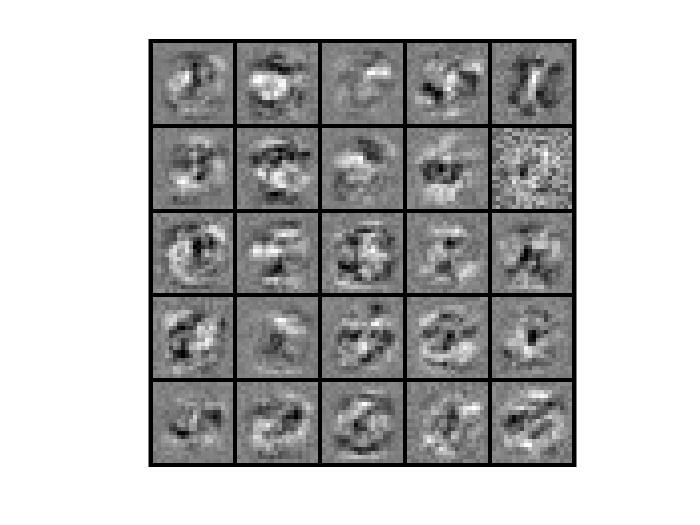

displayData(Theta1(:, 2:end));

17. Подберите параметр регуляризации. Как меняются изображения на скрытом слое в зависимости от данного параметра?

lambda = 0.3;
MaxIter = 50;
options = optimset('MaxIter', MaxIter);
costFunction = @(p) nnCostFunction(p,input_layer_size, hidden_layer_size, num_labels, X, y, lambda);
[nn_params, ~] = fmincg(costFunction, initial_nn_params, options);

Iteration 


Theta1 = reshape(nn_params(1:hidden_layer_size * (input_layer_size + 1)), hidden_layer_size, (input_layer_size + 1));
Theta2 = reshape(nn_params((1 + (hidden_layer_size * (input_layer_size + 1))):end), num_labels, (hidden_layer_size + 1));
 
pred = predict(Theta1, Theta2, X);


Training Set Accuracy: 94.720000


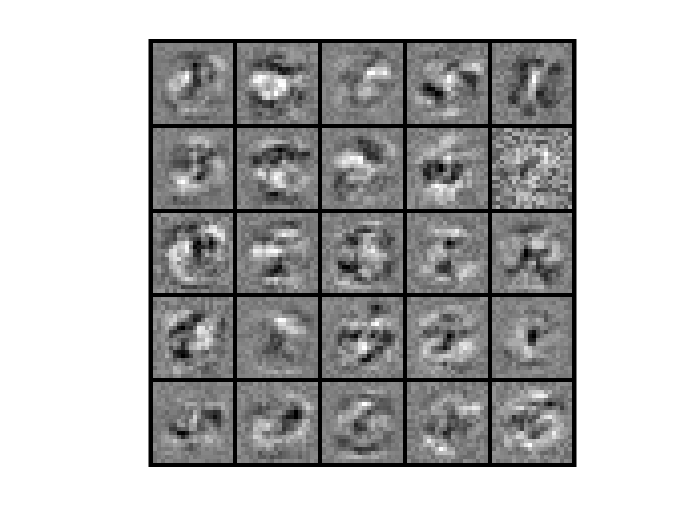

displayData(Theta1(:, 2:end));

lambda = 3;
MaxIter = 50;
options = optimset('MaxIter', MaxIter);
costFunction = @(p) nnCostFunction(p,input_layer_size, hidden_layer_size, num_labels, X, y, lambda);
[nn_params, ~] = fmincg(costFunction, initial_nn_params, options);

Theta1 = reshape(nn_params(1:hidden_layer_size * (input_layer_size + 1)), hidden_layer_size, (input_layer_size + 1));
Theta2 = reshape(nn_params((1 + (hidden_layer_size * (input_layer_size + 1))):end), num_labels, (hidden_layer_size + 1));
 
pred = predict(Theta1, Theta2, X);
displayData(Theta1(:, 2:end));
lambda = 30;
MaxIter = 50;
options = optimset('MaxIter', MaxIter);
costFunction = @(p) nnCostFunction(p,input_layer_size, hidden_layer_size, num_labels, X, y, lambda);
[nn_params, ~] = fmincg(costFunction, initial_nn_params, options);

Theta1 = reshape(nn_params(1:hidden_layer_size * (input_layer_size + 1)), hidden_layer_size, (input_layer_size + 1));
Theta2 = reshape(nn_params((1 + (hidden_layer_size * (input_layer_size + 1))):end), num_labels, (hidden_layer_size + 1));
 
pred = predict(Theta1, Theta2, X);
displayData(Theta1(:, 2:end));